# Mesh Generation

## Geometry generation with delaunayTriangulation and isInterior 

clear;
x1=[0.5, -0.5,  -0.5,  0.5 ];
y1=[0.5,  0.5,  -0.5, -0.5 ];
n1=size(x1,2);

x2=[0.4,  0.05,  0.05,  0.4];
y2=[0.4,  0.4 ,  0.05,  0.05];
n2=size(x2,2)+n1;

x3=[-0.4,  -0.05, -0.05,  -0.4];
y3=[0.4,   0.4,   0.05,   0.05];
n3=size(x3,2)+n2;

NN=25;r=0.15/2; 
dx=(0.5-2*r)*2/3+r;  dy=(0.55-2*r)/2+r;
theta=2*pi*(0:(NN-1))/NN;

x4= 0.5-dx+r*cos(theta);
y4=-0.5+dy+r*sin(theta);
n4=size(x4,2)+n3;

x5=-0.5+dx+r*cos(theta);
y5=-0.5+dy+r*sin(theta);
n5=size(x5,2)+n4;


nodes=[x1,x2,x3,x4,x5;y1,y2,y3,y4,y5];
edges=[1:n5; 2:n1,1, (n1+2):n2,(n1+1), (n2+2):n3, ...
    (n2+1), (n3+2):n4,(n3+1), (n4+2):n5,(n4+1)];

DT = delaunayTriangulation(nodes', edges');
TF = isInterior(DT);
elements=DT(TF,:)';

## Figure geometry and write data

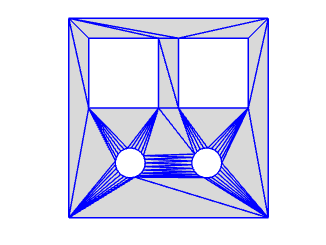

figure; 
patch('Faces',elements','Vertices',nodes','FaceColor',[0.85, 0.85, 0.85], ...
    'EdgeColor','blue');
% hold on
% text(nodes(1,:),nodes(2,:), 'n' + string(1:size(nodes,2)));

% hold on
% plot([nodes(1, edges(1,:));nodes(1, edges(2,:))] , ...
%      [nodes(2, edges(1,:)); nodes(2, edges(2,:))], ...
%      Color = 'r', Marker='.',MarkerEdgeColor='b', MarkerSize = 8);

% hold on
% text((nodes(1, edges(1,:)) + nodes(1, edges(2,:)))/2, ...
%      (nodes(2, edges(1,:)) + nodes(2, edges(2,:)))/2, ...
%     'e' + string(1:size(edges,2)));

axis equal off
geometrywrite(nodes, elements, edges, 'geometry.dat');
exportgraphics(gca,'FourHoles-Geo.pdf','ContentType','vector');

## Example 1: Default

### Mesh generation and Read mesh file ('meshradii.dat')

meshgeneration('geometry.dat','meshradii.dat'); 
[nodes, elements, radii] = meshradiiread('meshradii.dat');

### Figure Mesh

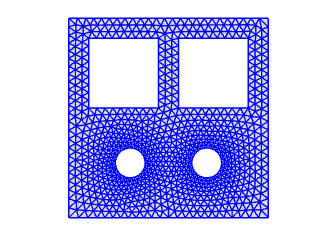

figure; 
patch('Faces',elements','Vertices',nodes','FaceColor',[0.85, 0.85, 0.85], ...
    'EdgeColor','b');

axis equal off
exportgraphics(gca,'FourHoles-MeshDefault.pdf','ContentType','vector');

### Figure Mesh with Bubbles

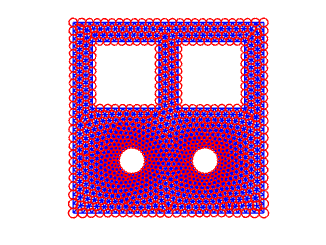

figure; 
patch('Faces',elements','Vertices',nodes','FaceColor',[0.85, 0.85, 0.85], ...
    'EdgeColor','b');

hold on  
for i=1:length(radii)
    r=radii(i);
    if r < 1e10
        rectangle('Position',[nodes(1,i)-r, nodes(2,i)-r, 2*r, 2*r], ...
    'Curvature', [1 1], 'EdgeColor','r');
    end
end
axis equal off

### Figure Mesh Quality Analysis

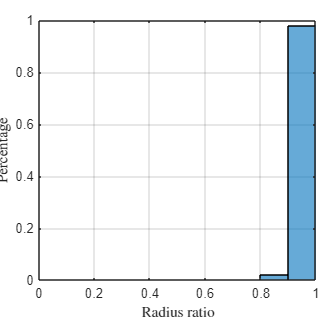

xs=nodes(1,:);ys=nodes(2,:);
t1=elements(1,:);t2=elements(2,:);t3=elements(3,:);
la=hypot(xs(t2)-xs(t1), ys(t2)-ys(t1));
lb=hypot(xs(t3)-xs(t1), ys(t3)-ys(t1));
lc=hypot(xs(t3)-xs(t2), ys(t3)-ys(t2));
rho=(lc+lb-la).*(lc+la-lb).*(la+lb-lc)./ (la.*lb.*lc);

figure;
histogram(rho,0:0.1:1,'Normalization','probability');
set(gcf,'Position',[230 250 400 400]) ;
set(gca,'Position',[0.12 0.14 0.85 0.8]);
xlim([0 1]);
xlabel('Radius ratio','interpreter','latex');
ylabel('Percentage','interpreter','latex');
grid on

## Example 2: Hgrad

### Mesh generation and Read mesh file ('meshradii.dat')

meshgeneration('geometry.dat','meshradii.dat', Hgrad=1.3); 
[nodes, elements, radii] = meshradiiread('meshradii.dat');

### Figure Mesh

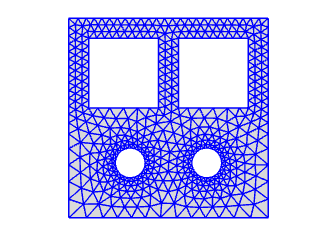

figure; 
patch('Faces',elements','Vertices',nodes','FaceColor',[0.85, 0.85, 0.85], ...
    'EdgeColor','b');

axis equal off
exportgraphics(gca,'FourHoles-MeshHgrad.pdf','ContentType','vector');

### Figure Mesh with Bubbles

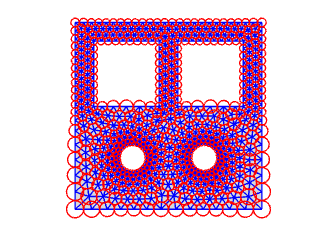

figure; 
patch('Faces',elements','Vertices',nodes','FaceColor',[0.85, 0.85, 0.85], ...
    'EdgeColor','b');

hold on  
for i=1:length(radii)
    r=radii(i);
    if r < 1e10
        rectangle('Position',[nodes(1,i)-r, nodes(2,i)-r, 2*r, 2*r], ...
    'Curvature', [1 1], 'EdgeColor','r');
    end
end
axis equal off

### Figure Mesh Quality Analysis

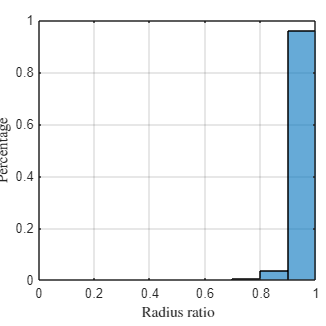

xs=nodes(1,:);ys=nodes(2,:);
t1=elements(1,:);t2=elements(2,:);t3=elements(3,:);
la=hypot(xs(t2)-xs(t1), ys(t2)-ys(t1));
lb=hypot(xs(t3)-xs(t1), ys(t3)-ys(t1));
lc=hypot(xs(t3)-xs(t2), ys(t3)-ys(t2));
rho=(lc+lb-la).*(lc+la-lb).*(la+lb-lc)./ (la.*lb.*lc);

figure;
histogram(rho,0:0.1:1,'Normalization','probability');
set(gcf,'Position',[230 250 400 400]) ;
set(gca,'Position',[0.12 0.14 0.85 0.8]);
xlim([0 1]);
xlabel('Radius ratio','interpreter','latex');
ylabel('Percentage','interpreter','latex');
grid on

## Example 3: Hmax

### Mesh generation and Read mesh file ('meshradii.dat')

meshgeneration('geometry.dat','meshradii.dat', Hmax=0.05, Hgrad=1.3); 
[nodes, elements, radii] = meshradiiread('meshradii.dat');

### Figure Mesh

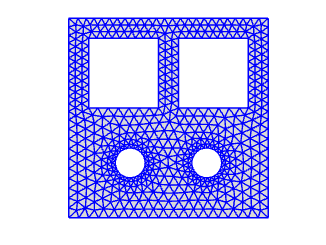

figure; 
patch('Faces',elements','Vertices',nodes','FaceColor',[0.85, 0.85, 0.85], ...
    'EdgeColor','b');

axis equal off
exportgraphics(gca,'FourHoles-MeshHmax.pdf','ContentType','vector');

### Figure Mesh with Bubbles

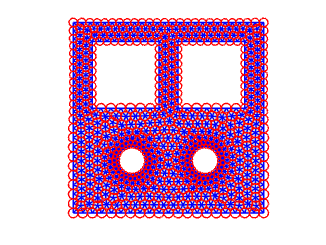

figure; 
patch('Faces',elements','Vertices',nodes','FaceColor',[0.85, 0.85, 0.85], ...
    'EdgeColor','b');

hold on  
for i=1:length(radii)
    r=radii(i);
    if r < 1e10
        rectangle('Position',[nodes(1,i)-r, nodes(2,i)-r, 2*r, 2*r], ...
    'Curvature', [1 1], 'EdgeColor','r');
    end
end
axis equal off

### Figure Mesh Quality Analysis

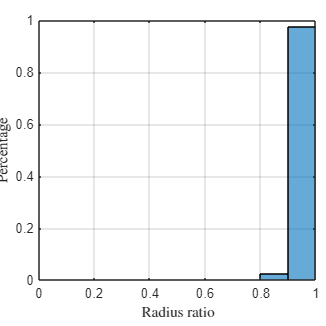

xs=nodes(1,:);ys=nodes(2,:);
t1=elements(1,:);t2=elements(2,:);t3=elements(3,:);
la=hypot(xs(t2)-xs(t1), ys(t2)-ys(t1));
lb=hypot(xs(t3)-xs(t1), ys(t3)-ys(t1));
lc=hypot(xs(t3)-xs(t2), ys(t3)-ys(t2));
rho=(lc+lb-la).*(lc+la-lb).*(la+lb-lc)./ (la.*lb.*lc);

figure;
histogram(rho,0:0.1:1,'Normalization','probability');
set(gcf,'Position',[230 250 400 400]) ;
set(gca,'Position',[0.12 0.14 0.85 0.8]);
xlim([0 1]);
xlabel('Radius ratio','interpreter','latex');
ylabel('Percentage','interpreter','latex');
grid on